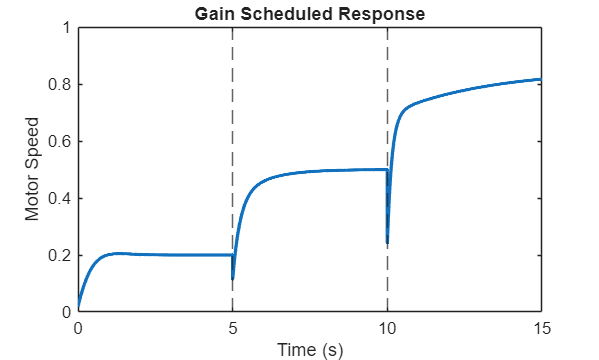

clc; clear; close all;

K = 1;
tau = 0.5;
G = tf(K,[tau 1]);

t_total = [];
y_total = [];

zones = [0.2 5; 0.5 5; 0.85 5];

for k = 1:size(zones,1)

    throttle = zones(k,1);
    duration = zones(k,2);

    if throttle < 0.3
        Kp=1.5; Ki=4; Kd=0.05;
    elseif throttle < 0.7
        Kp=2.5; Ki=3; Kd=0.15;
    else
        Kp=4; Ki=1.5; Kd=0.2;
    end

    C = pid(Kp,Ki,Kd);
    T = feedback(C*G,1);

    [y,t] = step(throttle*T,0:0.01:duration);

    if k>1
        t = t + t_total(end);
    end

    t_total = [t_total; t];
    y_total = [y_total; y];
end

figure;
plot(t_total,y_total,'LineWidth',2);
hold on
xline(5,'--');
xline(10,'--');

title('Gain Scheduled Response');
xlabel('Time (s)');
ylabel('Motor Speed');

if ~exist('results','dir')
    mkdir('results');
end

saveas(gcf,'results/gainscheduled_response.png');


save('gs_data.mat','t_total','y_total');